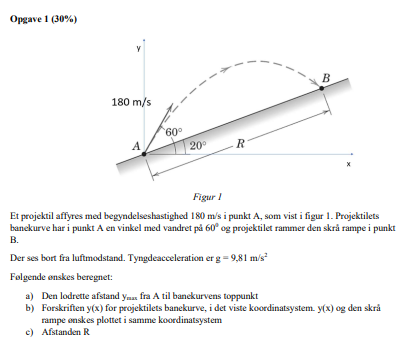

g = -9.81;
v0 = 180;
theta = deg2rad(60);
alpha = deg2rad(20)

alpha = 0.3491


% Hastighed i x og y
vx = v0 *cos(theta);
vy = v0 *sin(theta);

m = 1;

% Opgave a
syms y_max

U = m*g*y_max;
T = 1/2 *m*vy^2;

eq = U + T == 0;

sol = solve(eq, y_max);
y_max = vpa(sol,4)

$$y\_max = 1239.0$$

% Opgave b

syms t Sx Sy

eqx = Sx == vx*t;

% Der løses for tiden i x-ligningen
t = solve(eqx, t)

$$t = \frac{\mathrm{Sx}}{90}$$


% Tiden indsættes i stedfunktionen for y(x)
Sy = vpa(1/2.*g.*t^2 + vy.*t, 3)

$$Sy = 1.73\,\mathrm{Sx}-6.06e-4\,{\mathrm{Sx}}^{2}$$

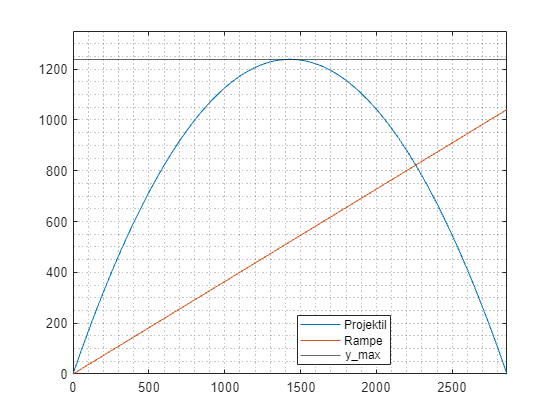


% distance i alt
eqSy = 1/2*g*t^2 + vy*t == 0;

x_pos = double(vpa(solve(eqSy, Sx),3))';


% Rampen
ramp = tan(alpha)*Sx;

% Der plottes
fplot(Sy, x_pos)

hold on
fplot(ramp, x_pos)

ylim([0, 1350]), yline(double(y_max)), grid("minor")

legend('Projektil', 'Rampe', 'y\_{max}', 'Location','best')
hold off


eq_inter = ramp == Sy;

Sx = max(solve(eq_inter, Sx))

$$Sx = 2259.2156256436135294481491905144$$


R = Sx/cos(alpha)

$$R = 2404.2070520401947445548991936672$$